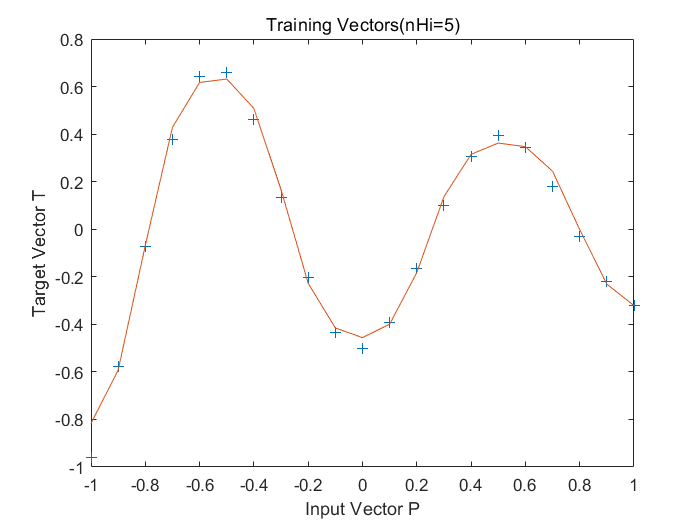

clf;
% rng('default');
rng(5);
rng;
%设定目标函数值
P = -1:.1:1;
T = [-.9602 -.5770 -.0729  .3771  .6405  .6600  .4609 ...
      .1336 -.2013 -.4344 -.5000 -.3930 -.1647  .0988 ...
      .3072  .3960  .3449  .1816 -.0312 -.2189 -.3201];
%设置训练超参数
maxiter = 2000;         %最大迭代次数
eta = 0.6;              %学习率
mc = 0.8;               %动量因子
eb = 0.000001;              %误差容限度
%建立网络
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
%训练隐藏层数目为5的网络
nHi = 5;                % 隐藏层数目
net=feedforwardnet(nHi, 'trainbfg');
[net,tr] = train(net, P, T);
train_out = sim(net, P);

plot(P,T,'+');
hold on;
plot(P,train_out);
title('Training Vectors(nHi=5)');
xlabel('Input Vector P');
ylabel('Target Vector T');

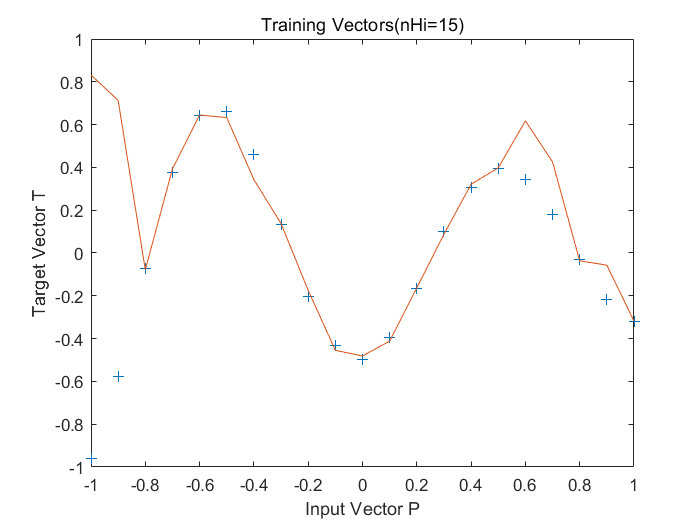

%训练隐藏层数目为15的网络
nHi = 15;                % 隐藏层数目
net=feedforwardnet(nHi, 'trainbfg');
[net,tr] = train(net, P, T);
train_out = sim(net, P);

figure;
plot(P,T,'+');
hold on;
plot(P,train_out);
title('Training Vectors(nHi=15)');
xlabel('Input Vector P');
ylabel('Target Vector T');


%结果分析：
%当其它条件不变，但隐藏层更多的时候，BP网络更容易过拟合。